% Paso 1: Pedir los valores de los puntos
n = input('Número de puntos: '); % Número de puntos

X = zeros(n, 1); % Inicializar vector de X
Y = zeros(n, 1); % Inicializar vector de Y

for i = 1:n
    X(i) = input(['X(' num2str(i) '): ']);
    Y(i) = input(['Y(' num2str(i) '): ']);
end

% ---------- MODELO LOGARÍTMICO ----------
% Verificar si X contiene valores mayores que 0 (para evitar logaritmo de 0 o negativos)
if any(X <= 0)
    error('Todos los valores de X deben ser positivos para el modelo logarítmico.');
end

% Tomar el logaritmo de X
X_log = log(X); % Logaritmo natural de X

% Construir la matriz A para el modelo logarítmico
A_logaritmico = [ones(n, 1), X_log]; % Matriz con columna de unos y valores de log(X)

% Calcular la fórmula de ajuste para el modelo logarítmico
At_logaritmico = A_logaritmico'; % Transpuesta de A_logaritmico
AtA_logaritmico = At_logaritmico * A_logaritmico; % A' * A
AtA_inv_logaritmico = inv(AtA_logaritmico); % Inversa de (A' * A)
AtY_logaritmico = At_logaritmico * Y; % A' * Y
u_logaritmico = AtA_inv_logaritmico * AtY_logaritmico; % Coeficientes de la ecuación logarítmica

% Obtener los coeficientes del modelo logarítmico
a_log = u_logaritmico(1); % Intercepto
b_log = u_logaritmico(2); % Coeficiente de log(X)

% Mostrar los coeficientes
disp('Coeficientes de la ecuación logarítmica:');

Coeficientes de la ecuación logarítmica:


disp(['a (intercepto): ' num2str(a_log)]);

a (intercepto): 4.7938


disp(['b (coeficiente de log(X)): ' num2str(b_log)]);

b (coeficiente de log(X)): -2.5724



% Evaluar Y_hat para el modelo logarítmico
Y_hat_logaritmico = a_log + b_log * log(X);

% Cálculo del ECM para el modelo logarítmico
ECM_logaritmico = sum((Y - Y_hat_logaritmico).^2) / n;

% Mostrar el ECM
disp(['Error Cuadrático Medio (ECM) - Modelo Logarítmico: ' num2str(ECM_logaritmico)]);

Error Cuadrático Medio (ECM) - Modelo Logarítmico: 1.3939


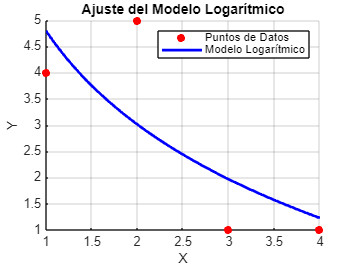


% ---------- GRAFICAR RESULTADOS ----------
% Crear una figura
figure;

% Graficar los datos originales
scatter(X, Y, 'ro', 'filled', 'DisplayName', 'Puntos de Datos');
hold on;

% Crear un rango de X para graficar la función logarítmica ajustada
X_plot = linspace(min(X), max(X), 100)';
Y_plot = a_log + b_log * log(X_plot);

% Graficar la curva logarítmica ajustada
plot(X_plot, Y_plot, 'b-', 'LineWidth', 2, 'DisplayName', 'Modelo Logarítmico');
xlabel('X');
ylabel('Y');
title('Ajuste del Modelo Logarítmico');
legend('show');
grid on;